T = 10e-3;

control_input = 1;

Found algebraic loop that contains: 
discrete_PID_anti_windup/PID/Saturation  (discontinuity)
discrete_PID_anti_windup/PID/Sum1 (algebraic variable)
discrete_PID_anti_windup/PID/Gain
discrete_PID_anti_windup/PID/Multiply
discrete_PID_anti_windup/PID/Sum2
discrete_PID_anti_windup/PID/Discrete-Time Integrator (discontinuity)


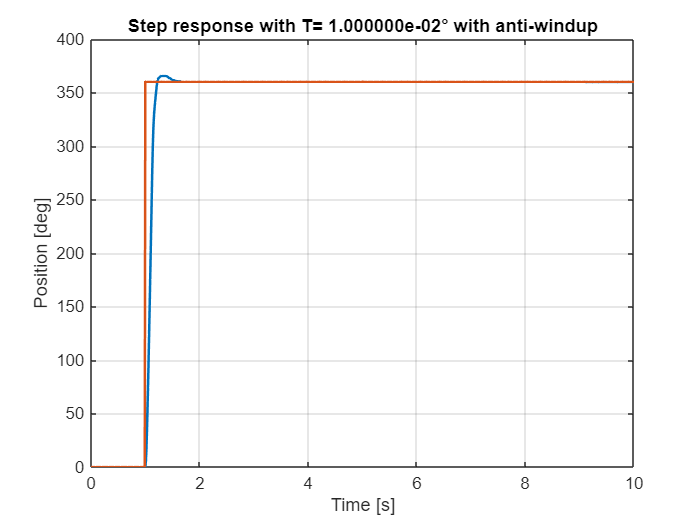


load_system('discrete_PID_anti_windup_3_1_1_b');
set_param('discrete_PID_anti_windup_3_1_1_b', 'SimulationCommand', 'start');

pause(3);  

t_3_1_1_b_windup = out_real_system.theta.time;

th_3_1_1_b_windup = out_real_system.theta.signals.values;

% Create plots
% Define the step amplitude vector

figure; 
plot(t_3_1_1_b_windup,th_3_1_1_b_windup, 'LineWidth', 1.5);
grid on;
title(sprintf('Step response with T= %d° with anti-windup', T));
xlabel('Time [s]');
ylabel('Position [deg]');

Found algebraic loop that contains: 
discrete_PID_anti_windup/PID/Saturation  (discontinuity)
discrete_PID_anti_windup/PID/Sum1 (algebraic variable)
discrete_PID_anti_windup/PID/Gain
discrete_PID_anti_windup/PID/Multiply
discrete_PID_anti_windup/PID/Sum2
discrete_PID_anti_windup/PID/Discrete-Time Integrator (discontinuity)


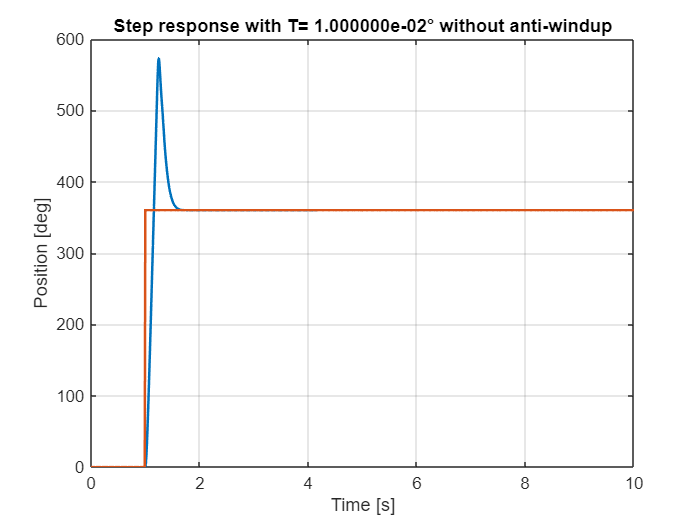

control_input = 0;

load_system('discrete_PID_anti_windup_3_1_1_b');
set_param('discrete_PID_anti_windup_3_1_1_b', 'SimulationCommand', 'start');

pause(3);  

t_3_1_1_b_no_windup = out_real_system.theta.time;

th_3_1_1_b_no_windup = out_real_system.theta.signals.values;

% Create plots
% Define the step amplitude vector

figure; 
plot(t_3_1_1_b_no_windup,th_3_1_1_b_no_windup, 'LineWidth', 1.5);
grid on;
title(sprintf('Step response with T= %d° with anti-windup', T));
xlabel('Time [s]');
ylabel('Position [deg]');